# S-CURVE TRACKER

response amplitude increased steadly, record forcing amplitude

close all;
clear all;

% define parameters for CL_model_reset (needed for CL control initialization)
w0 = 2*pi;
% target = 5;
x_init = [0, 0];
periods = 30;
dt = 1/1000;
invasive_tol = 5/100;

% create 
response_amplitudes = linspace(2.3, 6.5, 21);
forcing_amplitudes = zeros(size(response_amplitudes));

for i = (1:length(response_amplitudes))
    target = response_amplitudes(i)

    % reset structures
    [model, input, trial, control] = CL_model_reset(w0,target, x_init, periods, dt);

    % get non-invasive control at target response amplitude
    [experiment, input3, trial3, control2, success] = harmonizer_newton(invasive_tol, model, input, trial, control);
    
    if success == false %skip if harmonizer fails
        continue;
    end

    % get forcing amplitudes
    [~, x_lin] = get_last_n_periods(trial3.t_span, input3.f_history, 10);
    forcing_amplitudes(i) = max(x_lin);

    % get actual response amplitude
    [~, x_lin] = get_last_n_periods(trial3.t_span, trial3.X(:, 1), 10);
    response_amplitudes(i) = max(x_lin);
    "s-curve tracker: Iteration number = " + i
end

target = 2.3000

Kd = 239.7000

Kp = 239.7000

ans = "get_response_target: response amp -> 2.3054"

ans = "get_response_target: response amp -> 2.3034"

ans = "Harmony Loop: 2 -> invasiveness: 5.8001"

ans =     2.8037  -58.7088         0    2.3000
   -0.1317   -0.1502    0.0010    0.0010
    0.2583   -3.3992    0.0010    0.0010
   -0.5010   -0.7200    0.0010    0.0010
   -0.7304   -1.1649    0.0010    0.0010
   -0.9767   -1.7203    0.0010    0.0010
   -1.2209   -2.3955    0.0010    0.0010


ans = "get_response_target: response amp -> 2.3145"

ans = "Harmony Loop: 3 -> invasiveness: 0.33556"

ans =    -0.5148  -58.7321         0    2.3000
   -0.0001    0.0015    0.0000    0.0000
    0.1965    0.0151   -0.0002   -0.0091
   -0.0002   -0.0006    0.0000    0.0000
   -0.0021    0.0366    0.0000    0.0000
   -0.0002    0.0000    0.0000    0.0000
   -0.0002   -0.0001    0.0000    0.0000


ans = "~~~~~~~~~~~~~~~~~~~~~~~~~~ Non-invasive control achieved! ~~~~~~~~~~~~~~~~~~~~~~~~~~"

ans =    -0.5148  -58.7321         0    2.3000
   -0.0001    0.0015    0.0000    0.0000
    0.1965    0.0151   -0.0002   -0.0091
   -0.0002   -0.0006    0.0000    0.0000
   -0.0021    0.0366    0.0000    0.0000
   -0.0002    0.0000    0.0000    0.0000
   -0.0002   -0.0001    0.0000    0.0000


ans = "s-curve tracker: Iteration number = 1"

target = 2.5100

Kd = 239.7000

Kp = 239.7000

ans = "get_response_target: response amp -> 2.5157"

ans = "get_response_target: response amp -> 2.5137"

ans = "Harmony Loop: 2 -> invasiveness: 6.9476"

ans =     2.5712  -62.1720         0    2.5100
   -0.1330   -0.1475    0.0010    0.0010
    0.3357   -4.3101    0.0010    0.0010
   -0.5191   -0.7067    0.0010    0.0010
   -0.7654   -1.1407    0.0010    0.0010
   -1.0406   -1.6810    0.0010    0.0010
   -1.3249   -2.3383    0.0010    0.0010


ans = "get_response_target: response amp -> 2.5278"

ans = "Harmony Loop: 3 -> invasiveness: 0.39441"

ans =    -0.5513  -62.1590         0    2.5100
   -0.0001    0.0017    0.0000    0.0000
    0.2267    0.0935   -0.0001   -0.0121
   -0.0003   -0.0010    0.0000    0.0000
   -0.0033    0.0579    0.0000    0.0000
   -0.0002   -0.0001    0.0000    0.0000
   -0.0003   -0.0003    0.0000    0.0000


ans = "~~~~~~~~~~~~~~~~~~~~~~~~~~ Non-invasive control achieved! ~~~~~~~~~~~~~~~~~~~~~~~~~~"

ans =    -0.5513  -62.1590         0    2.5100
   -0.0001    0.0017    0.0000    0.0000
    0.2267    0.0935   -0.0001   -0.0121
   -0.0003   -0.0010    0.0000    0.0000
   -0.0033    0.0579    0.0000    0.0000
   -0.0002   -0.0001    0.0000    0.0000
   -0.0003   -0.0003    0.0000    0.0000


ans = "s-curve tracker: Iteration number = 2"

target = 2.7200

Kd = 239.7000

Kp = 239.7000

ans = "get_response_target: response amp -> 2.726"

ans = "get_response_target: response amp -> 2.724"

ans = "Harmony Loop: 2 -> invasiveness: 8.2936"

ans =     2.6880  -65.1180         0    2.7200
   -0.1322   -0.1464    0.0010    0.0010
    0.4997   -5.3821    0.0010    0.0010
   -0.5191   -0.7062    0.0010    0.0010
   -0.7634   -1.1398    0.0010    0.0010
   -1.0402   -1.6797    0.0010    0.0010
   -1.3245   -2.3370    0.0010    0.0010


ans = "get_response_target: response amp -> 2.7421"

ans = "Harmony Loop: 3 -> invasiveness: 0.62485"

ans =    -0.5827  -65.0736         0    2.7200
   -0.0001    0.0021    0.0000    0.0000
    0.2605    0.3123   -0.0001   -0.0161
   -0.0003   -0.0013    0.0000    0.0000
   -0.0053    0.0901    0.0000    0.0000
   -0.0002   -0.0003    0.0000    0.0000
   -0.0003   -0.0007    0.0000    0.0000


ans = "~~~~~~~~~~~~~~~~~~~~~~~~~~ Non-invasive control achieved! ~~~~~~~~~~~~~~~~~~~~~~~~~~"

ans =    -0.5827  -65.0736         0    2.7200
   -0.0001    0.0021    0.0000    0.0000
    0.2605    0.3123   -0.0001   -0.0161
   -0.0003   -0.0013    0.0000    0.0000
   -0.0053    0.0901    0.0000    0.0000
   -0.0002   -0.0003    0.0000    0.0000
   -0.0003   -0.0007    0.0000    0.0000


ans = "s-curve tracker: Iteration number = 3"

target = 2.9300

Kd = 239.7000

Kp = 239.7000

ans = "get_response_target: response amp -> 2.9362"

ans = "get_response_target: response amp -> 2.9342"

ans = "Harmony Loop: 2 -> invasiveness: 9.8682"

ans =     2.3600  -67.5379         0    2.9300
   -0.1334   -0.1438    0.0010    0.0010
    0.5613   -6.6452    0.0010    0.0010
   -0.5369   -0.6923    0.0010    0.0010
   -0.7963   -1.1143    0.0010    0.0010
   -1.1024   -1.6379    0.0010    0.0010
   -1.4257   -2.2751    0.0010    0.0010


ans = "get_response_target: response amp -> 2.9565"

ans = "Harmony Loop: 3 -> invasiveness: 0.76671"

ans =    -0.6073  -67.4356         0    2.9300
   -0.0001    0.0023    0.0000    0.0000
    0.3024    0.4194   -0.0001   -0.0203
   -0.0003   -0.0019    0.0000    0.0000
   -0.0071    0.1319    0.0000    0.0000
   -0.0002   -0.0005    0.0000    0.0000
   -0.0005   -0.0012    0.0000    0.0000


ans = "~~~~~~~~~~~~~~~~~~~~~~~~~~ Non-invasive control achieved! ~~~~~~~~~~~~~~~~~~~~~~~~~~"

ans =    -0.6073  -67.4356         0    2.9300
   -0.0001    0.0023    0.0000    0.0000
    0.3024    0.4194   -0.0001   -0.0203
   -0.0003   -0.0019    0.0000    0.0000
   -0.0071    0.1319    0.0000    0.0000
   -0.0002   -0.0005    0.0000    0.0000
   -0.0005   -0.0012    0.0000    0.0000


ans = "s-curve tracker: Iteration number = 4"

target = 3.1400

Kd = 239.7000

Kp = 239.7000

ans = "get_response_target: response amp -> 3.1463"

ans = "get_response_target: response amp -> 3.1444"

ans = "Harmony Loop: 2 -> invasiveness: 11.7111"

ans =     2.4243  -69.3583         0    3.1400
   -0.1325   -0.1429    0.0010    0.0010
    0.7443   -8.0934    0.0010    0.0010
   -0.5370   -0.6917    0.0010    0.0010
   -0.7927   -1.1131    0.0010    0.0010
   -1.1019   -1.6364    0.0010    0.0010
   -1.4253   -2.2737    0.0010    0.0010


ans = "get_response_target: response amp -> 3.1724"

ans = "Harmony Loop: 3 -> invasiveness: 1.2794"

ans =    -0.6237  -69.1926         0    3.1400
   -0.0001    0.0028    0.0000    0.0000
    0.3530    0.8119   -0.0000   -0.0260
   -0.0004   -0.0024    0.0000    0.0000
   -0.0103    0.1944    0.0000    0.0000
   -0.0002   -0.0008    0.0000    0.0000
   -0.0006   -0.0021    0.0000    0.0000


ans = "~~~~~~~~~~~~~~~~~~~~~~~~~~ Non-invasive control achieved! ~~~~~~~~~~~~~~~~~~~~~~~~~~"

ans =    -0.6237  -69.1926         0    3.1400
   -0.0001    0.0028    0.0000    0.0000
    0.3530    0.8119   -0.0000   -0.0260
   -0.0004   -0.0024    0.0000    0.0000
   -0.0103    0.1944    0.0000    0.0000
   -0.0002   -0.0008    0.0000    0.0000
   -0.0006   -0.0021    0.0000    0.0000


ans = "s-curve tracker: Iteration number = 5"

target = 3.3500

Kd = 239.7000

Kp = 239.7000

ans = "get_response_target: response amp -> 3.3564"

ans = "get_response_target: response amp -> 3.3545"

ans = "Harmony Loop: 2 -> invasiveness: 13.8745"

ans =     2.4720  -70.5536         0    3.3500
   -0.1316   -0.1420    0.0010    0.0010
    0.9468   -9.7491    0.0010    0.0010
   -0.5370   -0.6911    0.0010    0.0010
   -0.7880   -1.1116    0.0010    0.0010
   -1.1013   -1.6349    0.0010    0.0010
   -1.4248   -2.2721    0.0010    0.0010


ans = "get_response_target: response amp -> 3.3895"

ans = "Harmony Loop: 3 -> invasiveness: 2.0798"

ans =    -0.6297  -70.2991         0    3.3500
   -0.0001    0.0034    0.0000    0.0000
    0.4137    1.4024   -0.0000   -0.0331
   -0.0004   -0.0031    0.0000    0.0000
   -0.0142    0.2815    0.0000    0.0000
   -0.0003   -0.0011    0.0000    0.0000
   -0.0009   -0.0035    0.0000    0.0000


ans = "~~~~~~~~~~~~~~~~~~~~~~~~~~ Non-invasive control achieved! ~~~~~~~~~~~~~~~~~~~~~~~~~~"

ans =    -0.6297  -70.2991         0    3.3500
   -0.0001    0.0034    0.0000    0.0000
    0.4137    1.4024   -0.0000   -0.0331
   -0.0004   -0.0031    0.0000    0.0000
   -0.0142    0.2815    0.0000    0.0000
   -0.0003   -0.0011    0.0000    0.0000
   -0.0009   -0.0035    0.0000    0.0000


ans = "s-curve tracker: Iteration number = 6"

target = 3.5600

Kd = 239.7000

Kp = 239.7000

ans = "get_response_target: response amp -> 3.5665"

ans = "get_response_target: response amp -> 3.5645"

ans = "Harmony Loop: 2 -> invasiveness: 16.4279"

ans =     2.0566  -71.0970         0    3.5600
   -0.1326   -0.1396    0.0010    0.0010
    0.9488  -11.6460    0.0010    0.0010
   -0.5544   -0.6767    0.0010    0.0010
   -0.8165   -1.0847    0.0010    0.0010
   -1.1617   -1.5906    0.0010    0.0010
   -1.5229   -2.2057    0.0010    0.0010


ans = "get_response_target: response amp -> 3.6053"

ans = "Harmony Loop: 3 -> invasiveness: 1.9817"

ans =    -1.0673  -70.7286         0    3.5600
   -0.0001    0.0037    0.0000    0.0000
    0.4735    1.3194    0.0000   -0.0388
   -0.0007   -0.0037    0.0000    0.0000
   -0.0054    0.3743    0.0000    0.0000
   -0.0004   -0.0015    0.0000    0.0000
   -0.0016   -0.0050    0.0000    0.0000


ans = "~~~~~~~~~~~~~~~~~~~~~~~~~~ Non-invasive control achieved! ~~~~~~~~~~~~~~~~~~~~~~~~~~"

ans =    -1.0673  -70.7286         0    3.5600
   -0.0001    0.0037    0.0000    0.0000
    0.4735    1.3194    0.0000   -0.0388
   -0.0007   -0.0037    0.0000    0.0000
   -0.0054    0.3743    0.0000    0.0000
   -0.0004   -0.0015    0.0000    0.0000
   -0.0016   -0.0050    0.0000    0.0000


ans = "s-curve tracker: Iteration number = 7"

target = 3.7700

Kd = 239.7000

Kp = 239.7000

ans = "get_response_target: response amp -> 3.7764"

ans = "get_response_target: response amp -> 3.7744"

ans = "Harmony Loop: 2 -> invasiveness: 19.4648"

ans =     2.0739  -70.9187         0    3.7700
   -0.1315   -0.1389    0.0010    0.0010
    1.1484  -13.7623    0.0010    0.0010
   -0.5545   -0.6759    0.0010    0.0010
   -0.8088   -1.0829    0.0010    0.0010
   -1.1610   -1.5888    0.0010    0.0010
   -1.5224   -2.2039    0.0010    0.0010


ans = "get_response_target: response amp -> 3.8242"

ans = "Harmony Loop: 3 -> invasiveness: 2.9425"

ans =    -1.0437  -70.4045         0    3.7700
   -0.0000    0.0043    0.0000    0.0000
    0.5479    1.9981    0.0001   -0.0478
   -0.0008   -0.0045    0.0000    0.0000
   -0.0061    0.5171    0.0000    0.0000
   -0.0005   -0.0019    0.0000    0.0000
   -0.0022   -0.0078    0.0000    0.0000


ans = "~~~~~~~~~~~~~~~~~~~~~~~~~~ Non-invasive control achieved! ~~~~~~~~~~~~~~~~~~~~~~~~~~"

ans =    -1.0437  -70.4045         0    3.7700
   -0.0000    0.0043    0.0000    0.0000
    0.5479    1.9981    0.0001   -0.0478
   -0.0008   -0.0045    0.0000    0.0000
   -0.0061    0.5171    0.0000    0.0000
   -0.0005   -0.0019    0.0000    0.0000
   -0.0022   -0.0078    0.0000    0.0000


ans = "s-curve tracker: Iteration number = 8"

target = 3.9800

Kd = 239.7000

Kp = 239.7000

ans = "get_response_target: response amp -> 3.9863"

ans = "get_response_target: response amp -> 3.9843"

ans = "Harmony Loop: 2 -> invasiveness: 23.1139"

ans =     2.0817  -69.9922         0    3.9800
   -0.1305   -0.1383    0.0010    0.0010
    1.3603  -16.1278    0.0010    0.0010
   -0.5545   -0.6751    0.0010    0.0010
   -0.7991   -1.0807    0.0010    0.0010
   -1.1603   -1.5870    0.0010    0.0010
   -1.5217   -2.2021    0.0010    0.0010


ans = "get_response_target: response amp -> 4.0445"

ans = "Harmony Loop: 3 -> invasiveness: 4.2497"

ans =    -0.9972  -69.2871         0    3.9800
    0.0001    0.0050    0.0000    0.0000
    0.6302    2.8766    0.0001   -0.0583
   -0.0009   -0.0055    0.0000    0.0000
   -0.0062    0.7041    0.0000    0.0000
   -0.0005   -0.0024    0.0000    0.0000
   -0.0031   -0.0118    0.0000    0.0000


ans = "~~~~~~~~~~~~~~~~~~~~~~~~~~ Non-invasive control achieved! ~~~~~~~~~~~~~~~~~~~~~~~~~~"

ans =    -0.9972  -69.2871         0    3.9800
    0.0001    0.0050    0.0000    0.0000
    0.6302    2.8766    0.0001   -0.0583
   -0.0009   -0.0055    0.0000    0.0000
   -0.0062    0.7041    0.0000    0.0000
   -0.0005   -0.0024    0.0000    0.0000
   -0.0031   -0.0118    0.0000    0.0000


ans = "s-curve tracker: Iteration number = 9"

target = 4.1900

Kd = 239.7000

Kp = 239.7000

ans = "get_response_target: response amp -> 4.1961"

ans = "get_response_target: response amp -> 4.1941"

ans = "Harmony Loop: 2 -> invasiveness: 27.5558"

ans =     2.0820  -68.2767         0    4.1900
   -0.1293   -0.1379    0.0010    0.0010
    1.5823  -18.7563    0.0010    0.0010
   -0.5546   -0.6743    0.0010    0.0010
   -0.7871   -1.0783    0.0010    0.0010
   -1.1596   -1.5851    0.0010    0.0010
   -1.5211   -2.2002    0.0010    0.0010


ans = "get_response_target: response amp -> 4.2665"

ans = "Harmony Loop: 3 -> invasiveness: 5.9868"

ans =    -0.9245  -67.3252         0    4.1900
    0.0001    0.0058    0.0000    0.0000
    0.7186    3.9665    0.0001   -0.0704
   -0.0010   -0.0065    0.0000    0.0000
   -0.0053    0.9451    0.0001    0.0000
   -0.0005   -0.0031    0.0000    0.0000
   -0.0045   -0.0177    0.0000    0.0000


ans = "get_response_target: response amp -> 4.2545"

ans = "Harmony Loop: 4 -> invasiveness: 1.073"

ans =    -0.9122  -67.5002         0    4.1900
   -0.0002    0.0002    0.0000    0.0001
    0.7238   -0.0282   -0.0006   -0.0579
    0.0005   -0.0003   -0.0000    0.0000
   -0.0303    0.3373    0.0001    0.0005
    0.0004    0.0005   -0.0000    0.0000
    0.0034   -0.0039   -0.0000   -0.0000


ans = "~~~~~~~~~~~~~~~~~~~~~~~~~~ Non-invasive control achieved! ~~~~~~~~~~~~~~~~~~~~~~~~~~"

ans =    -0.9122  -67.5002         0    4.1900
   -0.0002    0.0002    0.0000    0.0001
    0.7238   -0.0282   -0.0006   -0.0579
    0.0005   -0.0003   -0.0000    0.0000
   -0.0303    0.3373    0.0001    0.0005
    0.0004    0.0005   -0.0000    0.0000
    0.0034   -0.0039   -0.0000   -0.0000


ans = "s-curve tracker: Iteration number = 10"

target = 4.4000

Kd = 239.7000

Kp = 239.7000

ans = "get_response_target: response amp -> 4.4058"

ans = "get_response_target: response amp -> 4.4039"

ans = "Harmony Loop: 2 -> invasiveness: 33.0531"

ans =     1.6637  -65.7433         0    4.4000
   -0.1301   -0.1359    0.0010    0.0010
    1.4036  -21.6918    0.0010    0.0010
   -0.5716   -0.6593    0.0010    0.0010
   -0.8060   -1.0506    0.0010    0.0010
   -1.2178   -1.5382    0.0010    0.0010
   -1.6158   -2.1292    0.0010    0.0010


ans = "get_response_target: response amp -> 4.4811"

ans = "Harmony Loop: 3 -> invasiveness: 3.8633"

ans =    -0.8203  -64.6082         0    4.4000
    0.0002    0.0059    0.0000    0.0000
    0.6329    2.4146    0.0002   -0.0753
   -0.0011   -0.0069    0.0000    0.0000
   -0.0013    1.1151    0.0001    0.0000
   -0.0006   -0.0035    0.0000    0.0000
   -0.0058   -0.0211    0.0000    0.0000


ans = "~~~~~~~~~~~~~~~~~~~~~~~~~~ Non-invasive control achieved! ~~~~~~~~~~~~~~~~~~~~~~~~~~"

ans =    -0.8203  -64.6082         0    4.4000
    0.0002    0.0059    0.0000    0.0000
    0.6329    2.4146    0.0002   -0.0753
   -0.0011   -0.0069    0.0000    0.0000
   -0.0013    1.1151    0.0001    0.0000
   -0.0006   -0.0035    0.0000    0.0000
   -0.0058   -0.0211    0.0000    0.0000


ans = "s-curve tracker: Iteration number = 11"

target = 4.6100

Kd = 239.7000

Kp = 239.7000

ans = "get_response_target: response amp -> 4.6154"

ans = "get_response_target: response amp -> 4.6135"

ans = "Harmony Loop: 2 -> invasiveness: 40.0014"

ans =     1.6773  -62.3282         0    4.6100
   -0.1289   -0.1357    0.0010    0.0010
    1.5785  -24.8912    0.0010    0.0010
   -0.5717   -0.6583    0.0010    0.0010
   -0.7882   -1.0479    0.0010    0.0010
   -1.2170   -1.5362    0.0010    0.0010
   -1.6150   -2.1271    0.0010    0.0010


ans = "get_response_target: response amp -> 4.7031"

ans = "Harmony Loop: 3 -> invasiveness: 4.8566"

ans =    -1.0651  -60.8688         0    4.6100
    0.0003    0.0066   -0.0000    0.0000
    0.7145    2.8690    0.0002   -0.0877
   -0.0014   -0.0077    0.0000    0.0000
    0.0479    1.4272    0.0001    0.0000
   -0.0009   -0.0041    0.0000    0.0000
   -0.0094   -0.0290    0.0000    0.0000


ans = "~~~~~~~~~~~~~~~~~~~~~~~~~~ Non-invasive control achieved! ~~~~~~~~~~~~~~~~~~~~~~~~~~"

ans =    -1.0651  -60.8688         0    4.6100
    0.0003    0.0066   -0.0000    0.0000
    0.7145    2.8690    0.0002   -0.0877
   -0.0014   -0.0077    0.0000    0.0000
    0.0479    1.4272    0.0001    0.0000
   -0.0009   -0.0041    0.0000    0.0000
   -0.0094   -0.0290    0.0000    0.0000


ans = "s-curve tracker: Iteration number = 12"

target = 4.8200

Kd = 239.7000

Kp = 239.7000

ans = "get_response_target: response amp -> 4.8249"

ans = "get_response_target: response amp -> 4.823"

ans = "Harmony Loop: 2 -> invasiveness: 49.0253"

ans =     1.6968  -58.0031         0    4.8200
   -0.1277   -0.1356    0.0010    0.0010
    1.7498  -28.3945    0.0010    0.0010
   -0.5717   -0.6573    0.0010    0.0010
   -0.7668   -1.0450    0.0010    0.0010
   -1.2161   -1.5340    0.0010    0.0010
   -1.6142   -2.1249    0.0010    0.0010


ans = "get_response_target: response amp -> 4.9258"

ans = "Harmony Loop: 3 -> invasiveness: 5.8482"

ans =    -1.2116  -56.1600         0    4.8200
    0.0004    0.0072   -0.0000    0.0000
    0.7842    3.1901    0.0003   -0.1009
   -0.0018   -0.0085    0.0000    0.0000
    0.1229    1.7950    0.0001    0.0000
   -0.0012   -0.0048    0.0000    0.0000
   -0.0145   -0.0389    0.0000    0.0000


ans = "get_response_target: response amp -> 4.9162"

ans = "Harmony Loop: 4 -> invasiveness: 1.8563"

ans =    -0.8465  -56.3604         0    4.8200
   -0.0003    0.0010    0.0000    0.0001
    0.6601   -0.0117   -0.0004   -0.0906
    0.0009   -0.0013   -0.0000    0.0000
   -0.1168    1.0398    0.0002    0.0006
    0.0012    0.0003   -0.0000    0.0000
    0.0082   -0.0116   -0.0000   -0.0000


ans = "~~~~~~~~~~~~~~~~~~~~~~~~~~ Non-invasive control achieved! ~~~~~~~~~~~~~~~~~~~~~~~~~~"

ans =    -0.8465  -56.3604         0    4.8200
   -0.0003    0.0010    0.0000    0.0001
    0.6601   -0.0117   -0.0004   -0.0906
    0.0009   -0.0013   -0.0000    0.0000
   -0.1168    1.0398    0.0002    0.0006
    0.0012    0.0003   -0.0000    0.0000
    0.0082   -0.0116   -0.0000   -0.0000


ans = "s-curve tracker: Iteration number = 13"

target = 5.0300

Kd = 239.7000

Kp = 239.7000

ans = "get_response_target: response amp -> 5.0344"

ans = "get_response_target: response amp -> 5.0324"

ans = "Harmony Loop: 2 -> invasiveness: 61.1719"

ans =     1.7258  -52.7279         0    5.0300
   -0.1264   -0.1357    0.0010    0.0010
    1.9134  -32.2151    0.0010    0.0010
   -0.5718   -0.6563    0.0010    0.0010
   -0.7413   -1.0418    0.0010    0.0010
   -1.2151   -1.5317    0.0010    0.0010
   -1.6134   -2.1225    0.0010    0.0010


ans = "get_response_target: response amp -> 5.1488"

ans = "Harmony Loop: 3 -> invasiveness: 6.6369"

ans =    -1.2358  -50.4438         0    5.0300
    0.0006    0.0078   -0.0000   -0.0000
    0.8146    3.2484    0.0003   -0.1146
   -0.0022   -0.0092    0.0000    0.0000
    0.2298    2.2168    0.0002    0.0000
   -0.0015   -0.0056    0.0000    0.0000
   -0.0217   -0.0508    0.0000    0.0000


ans = "get_response_target: response amp -> 5.139"

ans = "Harmony Loop: 4 -> invasiveness: 2.8071"

ans =    -0.5899  -50.6737         0    5.0300
   -0.0004    0.0012    0.0000    0.0001
    0.5928    0.0024   -0.0002   -0.1040
    0.0012   -0.0017   -0.0000    0.0000
   -0.1743    1.4118    0.0004    0.0007
    0.0017    0.0002   -0.0000    0.0000
    0.0125   -0.0156   -0.0000   -0.0000


ans = "~~~~~~~~~~~~~~~~~~~~~~~~~~ Non-invasive control achieved! ~~~~~~~~~~~~~~~~~~~~~~~~~~"

ans =    -0.5899  -50.6737         0    5.0300
   -0.0004    0.0012    0.0000    0.0001
    0.5928    0.0024   -0.0002   -0.1040
    0.0012   -0.0017   -0.0000    0.0000
   -0.1743    1.4118    0.0004    0.0007
    0.0017    0.0002   -0.0000    0.0000
    0.0125   -0.0156   -0.0000   -0.0000


ans = "s-curve tracker: Iteration number = 14"

target = 5.2400

Kd = 239.7000

Kp = 239.7000

ans = "get_response_target: response amp -> 5.2437"

ans = "get_response_target: response amp -> 5.2418"

ans = "Harmony Loop: 2 -> invasiveness: 78.339"

ans =     1.4763  -46.4732         0    5.2400
   -0.1270   -0.1343    0.0010    0.0010
    1.3790  -36.3989    0.0010    0.0010
   -0.5883   -0.6406    0.0010    0.0010
   -0.7437   -1.0154    0.0010    0.0010
   -1.2711   -1.4825    0.0010    0.0010
   -1.7044   -2.0471    0.0010    0.0010


ans = "get_response_target: response amp -> 5.3585"

ans = "Harmony Loop: 3 -> invasiveness: 5.5126"

ans =    -0.5646  -43.9971         0    5.2400
    0.0005    0.0073   -0.0000   -0.0000
    0.2301   -1.1076    0.0004   -0.1150
   -0.0020   -0.0089    0.0000    0.0000
    0.1855    2.4185    0.0002    0.0000
   -0.0013   -0.0059    0.0000    0.0000
   -0.0227   -0.0539    0.0000    0.0000


ans = "get_response_target: response amp -> 5.3629"

ans = "Harmony Loop: 4 -> invasiveness: 4.2675"

ans =    -0.5622  -43.9148         0    5.2400
   -0.0003    0.0022    0.0000    0.0000
    0.3699   -0.0231    0.0003   -0.1186
    0.0007   -0.0029   -0.0000    0.0000
   -0.0585    1.8733    0.0003    0.0007
    0.0013   -0.0003   -0.0000    0.0000
    0.0072   -0.0280   -0.0000   -0.0000


ans = "~~~~~~~~~~~~~~~~~~~~~~~~~~ Non-invasive control achieved! ~~~~~~~~~~~~~~~~~~~~~~~~~~"

ans =    -0.5622  -43.9148         0    5.2400
   -0.0003    0.0022    0.0000    0.0000
    0.3699   -0.0231    0.0003   -0.1186
    0.0007   -0.0029   -0.0000    0.0000
   -0.0585    1.8733    0.0003    0.0007
    0.0013   -0.0003   -0.0000    0.0000
    0.0072   -0.0280   -0.0000   -0.0000


ans = "s-curve tracker: Iteration number = 15"

target = 5.4500

Kd = 239.7000

Kp = 239.7000

ans = "get_response_target: response amp -> 5.4529"

ans = "get_response_target: response amp -> 5.451"

ans = "Harmony Loop: 2 -> invasiveness: 140.9115"

ans =    -1.0372   24.3484         0    5.4500
    0.3004   -7.4120    0.0010    0.0010
    0.8649  -34.3300    0.0010    0.0010
   -0.6499    1.3089    0.0010    0.0010
    0.4420    1.4457    0.0010    0.0010
    0.9814    1.4234    0.0010    0.0010
   -1.5884   -1.6332    0.0010    0.0010


ans = "get_response_target: response amp -> 5.4691"

ans = "Harmony Loop: 3 -> invasiveness: 91.8556"

ans = 7×4
    0.6172  -38.8111         0    5.4500
   -0.0779   -3.5965   -0.0004    0.0341
   -1.0448  -35.6394   -0.0003   -0.0163
   -0.0648   -2.2889   -0.0000    0.0027
    0.0307    1.5746    0.0003   -0.0013
    0.0636    0.4014   -0.0000   -0.0003
   -0.0382   -0.1889    0.0000    0.0001


ans = "get_response_target: response amp -> 5.0354"

ans = "Harmony Loop: 4 -> invasiveness: 499.4563"

ans = 7×4
   -1.1815   36.1424         0    5.4500
    0.1148   -0.9957   -0.0001    0.0653
   -2.1658 -180.5988    0.0004    0.4544
   -0.0340   -0.4287   -0.0001    0.0016
   -0.0583   29.1721    0.0002    0.0267
    0.1572    3.1834   -0.0001   -0.0009
   -0.1748    1.9638   -0.0000    0.0000


ans = "get_response_target: response amp -> 5.5851"

ans = "Harmony Loop: 5 -> invasiveness: 22.5125"

ans = 7×4
   -4.6367   35.7559         0    5.4500
    1.5870   -7.9603   -0.0003    0.0772
   -0.8284    0.5128   -0.0009   -0.1320
    1.2274   -2.3009   -0.0003    0.0014
    2.9280   -4.8638    0.0002   -0.0029
   -0.2551    0.3201    0.0000   -0.0003
   -0.1020    0.1924    0.0000    0.0001


ans = "get_response_target: response amp -> 5.5867"

ans = "Harmony Loop: 6 -> invasiveness: 18.5071"

ans = 7×4
   -0.3161  -36.1113         0    5.4500
   -0.5475   -6.6610   -0.0001    0.0636
    0.7398   -1.4369   -0.0017   -0.1304
   -0.2268   -2.4336   -0.0002    0.0017
    0.1533    1.7144    0.0002    0.0013
    0.1315    0.2695   -0.0000   -0.0002
   -0.1971   -0.2844    0.0001    0.0001


ans = "get_response_target: response amp -> 5.5846"

ans = "Harmony Loop: 7 -> invasiveness: 7.7116"

ans = 7×4
   -2.8193  -36.0039         0    5.4500
    0.1777    0.7446   -0.0001   -0.0064
    0.4365   -1.1627   -0.0013   -0.1316
    1.0818    2.1337   -0.0002   -0.0039
    1.2609    2.4832    0.0002    0.0002
   -0.0717   -0.1248   -0.0000    0.0002
   -0.1597   -0.2472   -0.0000    0.0001


ans = "get_response_target: response amp -> 5.5934"

ans = "Harmony Loop: 8 -> invasiveness: 2.3388"

ans = 7×4
   -1.4681  -35.9534         0    5.4500
    0.0078   -0.0327   -0.0001    0.0006
    0.7196    0.3733   -0.0008   -0.1368
    0.2896    0.6766   -0.0002   -0.0013
   -0.3211   -0.3202    0.0002    0.0038
    0.0166   -0.0506   -0.0000    0.0001
    0.5647   -0.6239   -0.0004    0.0001


ans = "~~~~~~~~~~~~~~~~~~~~~~~~~~ Non-invasive control achieved! ~~~~~~~~~~~~~~~~~~~~~~~~~~"

ans = 7×4
   -1.4681  -35.9534         0    5.4500
    0.0078   -0.0327   -0.0001    0.0006
    0.7196    0.3733   -0.0008   -0.1368
    0.2896    0.6766   -0.0002   -0.0013
   -0.3211   -0.3202    0.0002    0.0038
    0.0166   -0.0506   -0.0000    0.0001
    0.5647   -0.6239   -0.0004    0.0001


ans = "s-curve tracker: Iteration number = 16"

target = 5.6600

Kd = 239.7000

Kp = 239.7000

ans = "get_response_target: response amp -> 5.662"

ans = "get_response_target: response amp -> 5.6601"

ans = "Harmony Loop: 2 -> invasiveness: 207.8573"

ans = 7×4
   -1.3001   20.9431         0    5.6600
    0.3375   -5.7899    0.0010    0.0010
    1.4230  -43.5924    0.0010    0.0010
   -0.5406    0.9410    0.0010    0.0010
    0.5123    1.4684    0.0010    0.0010
   -0.8674   -0.6825    0.0010    0.0010
   -1.5638   -1.7081    0.0010    0.0010


ans = "get_response_target: response amp -> 5.8483"

ans = "Harmony Loop: 3 -> invasiveness: 37.7965"

ans = 7×4
   -1.5203   26.0241         0    5.6600
    0.1189   -5.1651   -0.0003    0.0500
    0.0523   -9.8528   -0.0001   -0.1856
    0.1840   -2.8777    0.0000    0.0028
    0.6823   -5.1695    0.0003   -0.0007
    0.0241   -0.4080    0.0000    0.0003
    0.0015    0.3023    0.0000    0.0001


ans = "get_response_target: response amp -> 5.9649"

ans = "Harmony Loop: 4 -> invasiveness: 202.8239"

ans = 7×4
    1.6067  -22.8249         0    5.6600
    1.4167  -46.3872   -0.0010    0.4555
   -1.2516   26.8260   -0.0001   -0.2401
    1.2391  -12.6203    0.0003    0.0014
   -3.3745    4.2514    0.0031    0.0006
   -0.2505    1.8142    0.0000   -0.0007
    0.0046   -0.6643    0.0000    0.0002


ans = "get_response_target: response amp -> 5.8618"

ans = "Harmony Loop: 5 -> invasiveness: 70.4868"

ans = 7×4
   18.6198    5.3658         0    5.6600
   -2.2719   -1.4779   -0.0002   -0.0008
   -9.8446   -9.4679   -0.0001   -0.2003
    1.5180   -0.4997   -0.0000    0.0032
   -0.1182   -4.8803    0.0008    0.0000
   -0.0721    0.1574    0.0000    0.0001
   -0.0336    0.4693    0.0000    0.0001


ans = "get_response_target: response amp -> 5.8743"

ans = "Harmony Loop: 6 -> invasiveness: 85.7224"

ans = 7×4
   18.4737    6.3098         0    5.6600
   -2.9298   -0.5566   -0.0007   -0.0158
   -9.9834  -13.4302   -0.0001   -0.2107
    1.0534   -0.5584    0.0016    0.0032
    1.1547   -4.7746    0.0007    0.0004
   -0.2232   -0.0065    0.0000    0.0002
   -0.2516    0.4472    0.0000    0.0002


ans = "get_response_target: response amp -> 5.854"

ans = "Harmony Loop: 7 -> invasiveness: 34.8308"

ans = 7×4
    2.2838  -26.2354         0    5.6600
   -0.4652    2.4265    0.0014   -0.0248
   -1.4401    6.2780    0.0031   -0.1754
   -2.8412   -1.3673    0.0052    0.0026
    1.1689   -9.0978    0.0008    0.0145
   -0.0383   -0.4108    0.0000    0.0002
    0.7125   -2.1618    0.0000    0.0010


ans = "get_response_target: response amp -> 5.8329"

ans = "Harmony Loop: 8 -> invasiveness: 96.9137"

ans = 7×4
   18.8655    6.5055         0    5.6600
   -3.0242   -0.5171    0.0018   -0.0175
   -5.4237   -8.9126    0.0036   -0.1867
    0.9130   -1.7276    0.0025    0.0037
   -2.8276  -19.1320   -0.0055   -0.0153
   -0.2107    0.3146    0.0000    0.0002
   -0.2320    0.3095    0.0000    0.0003


ans = "get_response_target: response amp -> 5.8842"

ans = "Harmony Loop: 9 -> invasiveness: 130.1225"

ans = 7×4
   23.3532  -11.7552         0    5.6600
   -1.5876   -1.2090    0.0013   -0.0188
    0.6909   -7.0983    0.0029   -0.1801
    2.1119    0.9737    0.0032   -0.0018
  -27.6713  -19.7910   -0.0011    0.0415
   -0.0138   -0.2255    0.0000    0.0002
    1.8212   -0.6016    0.0000    0.0004


ans = "get_response_target: response amp -> 6.3989"

ans = "Harmony Loop: 10 -> invasiveness: 24743.1"

ans = 7×4
1.0e+03 *

    0.0046   -0.0042         0    0.0057
   -0.0014   -0.0004    0.0000   -0.0000
   -0.0384   -0.0187    0.0000   -0.0002
    0.0006   -0.0046    0.0000    0.0000
   -0.0550   -1.5401   -0.0000   -0.0017
    0.0004    0.0043    0.0000    0.0000
    0.0397   -0.0070    0.0000    0.0000


ans = "get_response_target: response amp -> 5.9243"

ans = "Harmony Loop: 11 -> invasiveness: 211.5977"

ans = 7×4
   23.7849   -9.6174         0    5.6600
   -1.3874   -0.9121   -0.0024   -0.0154
    3.5958  -10.6579    0.0029   -0.1958
    1.2344    0.5982    0.0016   -0.0015
  -32.2699  -43.6544    0.0039    0.0637
    0.1727   -0.1436    0.0000    0.0002
    2.5023    0.5487    0.0000    0.0004


ans = "get_response_target: response amp -> 5.8152"

ans = "Harmony Loop: 12 -> invasiveness: 427.539"

ans = 7×4
    3.6031  -23.2579         0    5.6600
  -23.6652   -3.0616    0.2341   -0.0174
   -8.7591   24.4536    0.0029   -0.2509
   -7.3275   -2.5785    0.0026   -0.0013
   35.8808  -94.0082    0.0180    0.1140
    0.6045    0.3596    0.0000    0.0002
    2.6173   -2.8472    0.0000    0.0004


ans = "get_response_target: response amp -> 5.9118"

ans = "Harmony Loop: 13 -> invasiveness: 86.0296"

ans = 7×4
   19.3292   -2.0736         0    5.6600
   -0.5585    1.4878   -0.0172   -0.0145
  -15.1607    7.0608    0.0029   -0.2126
    0.6626    0.6750    0.0017   -0.0014
    1.9722  -16.5006    0.0106    0.0200
    0.2859    0.1806    0.0000    0.0002
    0.4190   -1.3265    0.0000    0.0004


ans = "get_response_target: response amp -> 5.882"

ans = "Harmony Loop: 14 -> invasiveness: 64.2815"

ans = 7×4
   20.1428    2.1477         0    5.6600
   -0.2707    1.2842   -0.0232   -0.0154
  -12.4799   -3.7164    0.0029   -0.1970
   -0.3574    0.9812    0.0018   -0.0014
   -0.8673  -10.5573    0.0102   -0.0000
   -0.0855    0.1950    0.0000    0.0002
    0.8383    0.2157    0.0000    0.0004


ans = "get_response_target: response amp -> 5.8572"

ans = "Harmony Loop: 15 -> invasiveness: 191.832"

ans = 7×4
   19.6576    4.9046         0    5.6600
   -1.4005    1.2236   -0.0290   -0.0213
  -10.7409  -11.0305    0.0030   -0.2024
   -0.7871    1.1111    0.0018   -0.0015
   -2.0143  -38.8134    0.0103   -0.0356
   -0.2966    0.0937    0.0000    0.0002
    0.3341    0.1406    0.0000    0.0004


ans = "get_response_target: response amp -> 5.8923"

ans = "Harmony Loop: 16 -> invasiveness: 56.2318"

ans = 7×4
   21.4889  -14.0242         0    5.6600
  -14.2356   -2.3556   -0.0219   -0.1400
   -2.6960  -11.8224    0.0033   -0.1943
    2.8805   -2.7419    0.0018   -0.0006
   -7.8768    9.3026    0.0101    0.0133
   -0.3770   -0.3665    0.0000    0.0002
    0.2415   -1.2559    0.0000    0.0004


ans = "get_response_target: response amp -> 6.0091"

ans = "Harmony Loop: 17 -> invasiveness: 257.0563"

ans = 7×4
   17.4689    7.0901         0    5.6600
   -3.3036    4.4955   -0.0297   -0.0619
  -18.1829  -44.9224    0.0034   -0.3152
    0.8839    0.4716    0.0018   -0.0012
    9.0234   -0.0413    0.0104    0.0038
    0.3054   -0.2428    0.0000    0.0002
    1.1374   -0.5444    0.0000    0.0004


ans = "get_response_target: response amp -> 5.8482"

ans = "Harmony Loop: 18 -> invasiveness: 44.4203"

ans = 7×4
    7.1591  -25.9245         0    5.6600
   -1.9778   11.7819   -0.0321   -0.1131
   -0.3938   -1.0126    0.0033   -0.1511
   -2.9769    1.9400    0.0018   -0.0011
   -4.1442   -8.6574    0.0102    0.0039
    0.3713   -0.1992    0.0000    0.0002
    0.9674   -0.2351    0.0000    0.0004


ans = "get_response_target: response amp -> 5.8472"

ans = "Harmony Loop: 19 -> invasiveness: 35.505"

ans = 7×4
    4.5444  -26.7106         0    5.6600
    2.7752    3.8804   -0.0357   -0.0303
   -0.2622   -1.9474    0.0033   -0.1473
   -0.8656    1.2565    0.0018   -0.0013
   -7.8196   -5.6032    0.0103    0.0038
    0.1141   -0.2847    0.0000    0.0002
    0.5760   -0.8056    0.0000    0.0004


ans = "get_response_target: response amp -> 5.8543"

ans = "Harmony Loop: 20 -> invasiveness: 35.4123"

ans = 7×4
    4.3445  -26.5409         0    5.6600
    3.5499   -0.2141   -0.0336    0.0104
   -1.1124    0.2563    0.0033   -0.1552
   -0.4264    0.4706    0.0018   -0.0015
   -8.0613   -5.0714    0.0102    0.0038
    0.0665   -0.2487    0.0000    0.0002
    0.5404   -0.8398    0.0000    0.0004


ans = "get_response_target: response amp -> 5.8618"

ans = "Harmony Loop: 21 -> invasiveness: 48.2784"

ans = 7×4
    5.1838  -26.4092         0    5.6600
    4.4237    0.5043   -0.0431    0.0083
   -1.1087   -0.1327    0.0033   -0.1543
   -0.3733    0.6552    0.0018   -0.0016
  -10.1276   -8.1398    0.0139    0.0030
    0.1363   -0.2575    0.0000    0.0002
    0.6474   -0.8572    0.0000    0.0004


ans = "get_response_target: response amp -> 5.8184"

ans = "Harmony Loop: 22 -> invasiveness: 14.5664"

ans = 7×4
   -1.4555  -26.8748         0    5.6600
   -0.7313   -0.8349    0.0049    0.0098
   -1.0759    0.7964    0.0055   -0.1546
   -0.9176    0.8173    0.0018   -0.0011
    3.0566   -2.4550   -0.0043    0.0050
    0.3539    0.6880    0.0000   -0.0005
    0.6249    0.0120   -0.0002   -0.0003


ans = "get_response_target: response amp -> 5.8258"

ans = "Harmony Loop: 23 -> invasiveness: 98.3797"

ans = 7×4
   23.7747   -2.8090         0    5.6600
   -1.1475    0.1234   -0.0019    0.0088
   -8.6268  -21.9153    0.0798   -0.1543
   -0.6112   -2.2620    0.0018   -0.0035
   -0.1226   -1.9578   -0.0001    0.0058
   -0.5401   -0.8478    0.0000    0.0000
   -8.7808   -9.6554   -0.0071   -0.0003


ans = "get_response_target: response amp -> 5.8124"

ans = "Harmony Loop: 24 -> invasiveness: 17.2345"

ans = 7×4
    0.4943  -26.9113         0    5.6600
   -1.8392   -0.7344    0.0169    0.0090
    1.8286    0.1585   -0.0050   -0.1546
   -1.2495    0.9524    0.0016   -0.0018
   -0.3703   -4.6240   -0.0003    0.0091
    0.0367    0.4459    0.0000   -0.0003
    1.2728    0.0018   -0.0007   -0.0003


ans = "get_response_target: response amp -> 5.8522"

ans = "Harmony Loop: 25 -> invasiveness: 12.8353"

ans = 7×4
   -4.0716  -26.5962         0    5.6600
    2.7845   -2.0427   -0.0330    0.0089
   -1.9669    1.8310    0.0098   -0.1546
    0.6101    0.9805    0.0019   -0.0023
    0.4214    0.5728   -0.0000    0.0034
    0.2274    0.2422    0.0000   -0.0002
    1.0962   -2.5671   -0.0015   -0.0003


ans = "get_response_target: response amp -> 5.825"

ans = "Harmony Loop: 26 -> invasiveness: 45.3648"

ans = 7×4
   -6.5132   26.1146         0    5.6600
    0.7813   -1.1149   -0.0030    0.0090
    0.5586   -0.1981    0.0021   -0.1546
    6.0178   -7.1484    0.0018    0.0158
   -0.0204   -0.2542   -0.0001    0.0040
    0.2794   -0.1595    0.0000   -0.0001
   -1.5599  -12.1097   -0.0066   -0.0003


ans = "get_response_target: response amp -> 5.8148"

ans = "Harmony Loop: 27 -> invasiveness: 24.7763"

ans = 7×4
   -2.2522  -26.8236         0    5.6600
   -1.1554   -0.6555    0.0087    0.0092
   -0.6169    0.7569    0.0038   -0.1546
   -1.2089    0.4714    0.0019   -0.0001
    0.2495    0.1730   -0.0001    0.0038
    0.0611    0.1503    0.0000   -0.0001
    4.5692   -4.8582   -0.0036   -0.0003


ans = "get_response_target: response amp -> 5.8217"

ans = "Harmony Loop: 28 -> invasiveness: 40.1303"

ans = 7×4
   -9.8745   25.0391         0    5.6600
    0.4306   -0.9274    0.0017    0.0095
    0.7203    0.2349    0.0029   -0.1546
    0.4597   -1.2528    0.0019    0.0009
    0.2454   -0.1646   -0.0001    0.0039
   -0.0448   -0.1125    0.0000   -0.0001
    7.7506   -7.5232   -0.0058   -0.0003


ans = "get_response_target: response amp -> 5.8189"

ans = "Harmony Loop: 29 -> invasiveness: 4.433"

ans = 7×4
    1.3053  -26.8870         0    5.6600
   -0.4195   -0.8723    0.0036    0.0086
   -0.7264    0.4629    0.0034   -0.1546
   -1.1463   -0.3316    0.0019    0.0002
    0.3318    0.2472   -0.0005    0.0039
   -0.0725    0.1229    0.0000   -0.0001
    0.7042    0.4399   -0.0004   -0.0003


ans = "~~~~~~~~~~~~~~~~~~~~~~~~~~ Non-invasive control achieved! ~~~~~~~~~~~~~~~~~~~~~~~~~~"

ans = 7×4
    1.3053  -26.8870         0    5.6600
   -0.4195   -0.8723    0.0036    0.0086
   -0.7264    0.4629    0.0034   -0.1546
   -1.1463   -0.3316    0.0019    0.0002
    0.3318    0.2472   -0.0005    0.0039
   -0.0725    0.1229    0.0000   -0.0001
    0.7042    0.4399   -0.0004   -0.0003


ans = "s-curve tracker: Iteration number = 17"

target = 5.8700

Kd = 239.7000

Kp = 239.7000

ans = "get_response_target: response amp -> 5.8709"

ans = "get_response_target: response amp -> 5.869"

ans = "Harmony Loop: 2 -> invasiveness: 329.6512"

ans = 7×4
   -1.4605   15.2643         0    5.8700
    0.2935   -3.9440    0.0010    0.0010
    1.0424  -50.5380    0.0010    0.0010
   -0.4050    0.5749    0.0010    0.0010
    0.5567    1.3424    0.0010    0.0010
   -1.0084   -0.8930    0.0010    0.0010
   -1.3266   -1.3999    0.0010    0.0010


ans = "get_response_target: response amp -> 6.1469"

ans = "Harmony Loop: 3 -> invasiveness: 292.1009"

ans = 7×4
    9.1756    4.6875         0    5.8700
    1.6093   -4.7134   -0.0004    0.0483
  -11.9831  -27.6087    0.0001   -0.2752
    1.8458    0.8637    0.0001    0.0024
    3.6973   -6.6170    0.0003   -0.0004
    0.1943   -0.2554    0.0000    0.0002
   -0.1786    0.1578    0.0000    0.0001


ans = "get_response_target: response amp -> 6.4847"

ans = "Harmony Loop: 4 -> invasiveness: 4001.5871"

ans = 7×4
    3.0256    0.9104         0    5.8700
  -17.1525   10.6876    0.0013   -0.2414
   -6.2361 -126.2800    0.0009   -0.6078
    4.1969    5.2348    0.0008   -0.0018
   11.4936   -6.0271    0.0011    0.0008
    0.5126   -1.3738    0.0002   -0.0001
    1.5263    0.7788   -0.0002    0.0002


ans = "get_response_target: response amp -> 6.0648"

ans = "Harmony Loop: 5 -> invasiveness: 43.2542"

ans = 7×4
  -12.4257  -10.6678         0    5.8700
    3.6472   -1.3202   -0.0003   -0.0404
    1.1113   -2.3370    0.0018   -0.1822
    0.2584    0.7645   -0.0005    0.0033
    7.0791   -0.2532   -0.0001    0.0129
    0.4118   -0.3483   -0.0001    0.0003
   -0.1575   -0.5770   -0.0000    0.0001


ans = "get_response_target: response amp -> 6.0581"

ans = "Harmony Loop: 6 -> invasiveness: 42.9586"

ans = 7×4
   -0.2908  -15.0450         0    5.8700
   -1.0348   -6.3810    0.0000   -0.0625
    0.2229   -0.8885    0.0017   -0.1741
   -0.1997   -0.3019   -0.0006    0.0041
   -1.4056   -5.7272   -0.0019    0.0134
    1.1035   -0.8976   -0.0012    0.0004
   -0.2457   -0.3433   -0.0000    0.0001


ans = "get_response_target: response amp -> 6.0507"

ans = "Harmony Loop: 7 -> invasiveness: 45.0811"

ans = 7×4
    0.7057  -16.7433         0    5.8700
    0.3482    3.2696   -0.0000   -0.0346
   -0.4666   -1.1932    0.0017   -0.1692
    0.0460   -1.3050   -0.0006    0.0039
   -0.2087   -7.5519   -0.0016    0.0129
   -0.7822   -0.2102    0.0005    0.0002
   -0.1865   -0.7736    0.0000    0.0002


ans = "get_response_target: response amp -> 6.0731"

ans = "Harmony Loop: 8 -> invasiveness: 48.0631"

ans = 7×4
    0.6088  -14.5062         0    5.8700
   -0.2740   -5.1674   -0.0000   -0.0441
   -0.1804   -5.1806    0.0017   -0.1885
   -0.0983    0.0060   -0.0006    0.0042
   -0.2544   -6.9736   -0.0016    0.0152
    0.2180    0.2648   -0.0002    0.0001
   -0.2714   -0.2904    0.0001    0.0000


ans = "get_response_target: response amp -> 6.0757"

ans = "Harmony Loop: 9 -> invasiveness: 210.1543"

ans = 7×4
   16.0133   -5.2502         0    5.8700
   -2.6932   -2.4917   -0.0000   -0.0383
   -1.1443    3.5642    0.0017   -0.1634
   -1.4088   -0.3103   -0.0006    0.0042
  -13.5594  -32.7167   -0.0019    0.0430
    0.3330   -0.1691   -0.0000    0.0002
    0.9507    1.0324   -0.0002   -0.0000


ans = "get_response_target: response amp -> 6.051"

ans = "Harmony Loop: 10 -> invasiveness: 18.6919"

ans = 7×4
   -0.3390  -16.6361         0    5.8700
    0.7138    3.0272   -0.0000   -0.0329
   -0.2412    0.2943    0.0017   -0.1736
   -0.3426   -1.4887   -0.0006    0.0042
   -0.0622   -2.8235   -0.0016    0.0077
    0.3048   -0.6697   -0.0005    0.0001
   -0.2811   -0.2658    0.0000    0.0000


ans = "get_response_target: response amp -> 6.0534"

ans = "Harmony Loop: 11 -> invasiveness: 43.0754"

ans = 7×4
   10.8098  -12.6164         0    5.8700
   -3.2055    1.1417   -0.0000   -0.0358
   -0.4483   -0.4797    0.0017   -0.1746
    0.4987    1.3698   -0.0006    0.0042
   -1.4155   -0.6059   -0.0016    0.0043
   -6.1484   -3.6624   -0.0053    0.0002
   -0.2801    0.0208   -0.0000    0.0000


ans = "get_response_target: response amp -> 6.0497"

ans = "Harmony Loop: 12 -> invasiveness: 263.9595"

ans = 7×4
   12.3354    4.7604         0    5.8700
   -4.5259   -0.2337   -0.0000   -0.0376
   -1.1692   -1.9292    0.0017   -0.1740
    0.5967   -0.8682   -0.0006    0.0042
   -0.6279   -3.2798   -0.0016    0.0034
   -0.6946   -0.9997   -0.0007    0.0001
   -2.5895  -34.8046   -0.0188    0.0000


ans = "get_response_target: response amp -> 6.0486"

ans = "Harmony Loop: 13 -> invasiveness: 25.0729"

ans = 7×4
    2.3681  -16.4399         0    5.8700
   -0.3393    3.5285   -0.0000   -0.0373
   -0.4220    0.5528    0.0017   -0.1748
    0.5963   -1.2717   -0.0006    0.0042
    1.1476    0.8012   -0.0016    0.0045
    0.2656   -0.2721   -0.0001    0.0001
   -3.7214   -1.8692    0.0023    0.0000


ans = "get_response_target: response amp -> 6.0559"

ans = "Harmony Loop: 14 -> invasiveness: 937.2917"

ans = 7×4
   12.3846    4.7236         0    5.8700
   -4.2838   -0.3795   -0.0000   -0.0376
   -1.0415   -2.6584    0.0017   -0.1746
   -0.6374    4.4842   -0.0110    0.0042
   -2.1895   -2.2231   -0.0016    0.0043
   -0.4905   -0.3385   -0.0003    0.0001
   -5.3183 -124.1229   -0.0671    0.0000


ans = "get_response_target: response amp -> 6.104"

ans = "Harmony Loop: 15 -> invasiveness: 2260.0432"

ans = 7×4
   13.4421    0.5749         0    5.8700
   -2.4201    3.0592   -0.0000   -0.0376
   -2.1748    0.0553    0.0017   -0.1747
    2.2942   -2.0914   -0.0056    0.0042
    0.2446   -3.8230   -0.0016    0.0045
    0.0386   -2.8624   -0.0002    0.0001
  -19.0566 -303.4769    0.1639    0.0000


ans = "get_response_target: response amp -> 6.1099"

ans = "Harmony Loop: 16 -> invasiveness: 2231.9604"

ans = 7×4
   12.1386    4.6521         0    5.8700
   -4.3887   -0.4969   -0.0000   -0.0376
   -1.0893   -2.8307    0.0016   -0.1747
   -0.8187    3.3695   -0.0099    0.0042
   -3.7652   -4.6200   -0.0016    0.0041
   -0.4252   -1.7956   -0.0002    0.0001
  -11.7166 -289.9064   -0.1565    0.0000


ans = "get_response_target: response amp -> 6.5658"

ans = "Harmony Loop: 17 -> invasiveness: 13147.533"

ans = 7×4
1.0e+03 *

    0.0087    0.0036         0    0.0059
   -0.0045   -0.0009   -0.0000   -0.0000
   -0.0010   -0.0036    0.0000   -0.0002
   -0.0025    0.0002   -0.0000    0.0000
   -0.0146   -0.0152   -0.0000    0.0000
   -0.0005   -0.0097   -0.0000    0.0000
   -0.0485   -1.2377   -0.0007    0.0000


ans = "get_response_target: response amp -> 6.0372"

ans = "Harmony Loop: 18 -> invasiveness: 69.5953"

ans = 7×4
    2.8898  -16.3535         0    5.8700
   -0.3113    3.6015    0.0000   -0.0376
   -0.3460    0.5725    0.0012   -0.1747
    6.0070    0.7351   -0.0104    0.0042
    0.3489    2.0944   -0.0016    0.0031
    0.6008   -0.0263   -0.0002    0.0001
   -9.2781   -6.8917    0.0062    0.0000


ans = "get_response_target: response amp -> 6.1008"

ans = "Harmony Loop: 19 -> invasiveness: 2325.077"

ans = 7×4
   13.1991    0.5907         0    5.8700
   -2.6323    3.1010    0.0000   -0.0376
   -2.5902    0.2199    0.0010   -0.1747
    3.9155   -2.2092   -0.0092    0.0042
   -0.2947   -3.8593   -0.0016    0.0035
    0.3068   -2.9003   -0.0002    0.0001
  -19.1302 -306.6000    0.1656    0.0000


ans = "get_response_target: response amp -> 6.103"

ans = "Harmony Loop: 20 -> invasiveness: 2047.4164"

ans = 7×4
   12.1492    4.6949         0    5.8700
   -4.4728   -0.4620    0.0000   -0.0376
   -1.2300   -2.6423    0.0013   -0.1747
   -0.4427    1.9612   -0.0071    0.0042
   -3.0359   -5.2500   -0.0016    0.0032
   -0.3677   -1.7150   -0.0002    0.0001
  -10.7675 -266.4543   -0.1438    0.0000


ans = "get_response_target: response amp -> 6.4467"

ans = "Harmony Loop: 21 -> invasiveness: 9434.9935"

ans = 7×4
1.0e+03 *

    0.0099    0.0039         0    0.0059
   -0.0046   -0.0008    0.0000   -0.0000
   -0.0011   -0.0034    0.0000   -0.0002
   -0.0018   -0.0001   -0.0000    0.0000
   -0.0111   -0.0139   -0.0000    0.0000
   -0.0005   -0.0077   -0.0000    0.0000
   -0.0395   -1.0047   -0.0005    0.0000


ans = "get_response_target: response amp -> 6.0405"

ans = "Harmony Loop: 22 -> invasiveness: 63.8654"

ans = 7×4
    3.4515  -16.2414         0    5.8700
   -0.6357    3.5402   -0.0003   -0.0376
   -0.9876    0.3186    0.0033   -0.1747
    4.1289    0.7008   -0.0070    0.0042
   -0.3181    2.4288   -0.0016    0.0027
    0.4703   -0.0196   -0.0001    0.0001
   -6.5622   -8.3299    0.0057    0.0000


ans = "get_response_target: response amp -> 6.0767"

ans = "Harmony Loop: 23 -> invasiveness: 1590.8911"

ans = 7×4
   13.4010    0.1871         0    5.8700
   -2.5522    2.5481   -0.0004   -0.0376
   -2.6070   -3.8826    0.0188   -0.1747
    2.8552   -0.6891   -0.0072    0.0042
   -1.1595   -1.6851   -0.0016    0.0029
    0.3816   -0.3245   -0.0001    0.0001
  -17.8775 -212.4655    0.1151    0.0000


ans = "get_response_target: response amp -> 6.0554"

ans = "Harmony Loop: 24 -> invasiveness: 823.0101"

ans = 7×4
   12.0336    4.8764         0    5.8700
   -4.8356   -0.2937   -0.0003   -0.0376
   -3.0920   -2.0845   -0.0062   -0.1747
    0.0672    2.6015   -0.0077    0.0042
   -1.1554   -3.6655   -0.0016    0.0028
   -0.3376   -0.3471   -0.0002    0.0001
   -4.5269 -106.7648   -0.0577    0.0000


ans = "get_response_target: response amp -> 6.0555"

ans = "Harmony Loop: 25 -> invasiveness: 1124.6762"

ans = 7×4
   19.0251    2.0770         0    5.8700
    5.2803   -1.1185   -0.0005   -0.0376
   37.3249  -13.1619    0.1533   -0.1747
   -4.6134    6.2257   -0.0077    0.0042
   -2.3180    1.1187   -0.0016    0.0030
   -1.4313    4.0954   -0.0002    0.0001
  -42.9071 -210.9225   -0.1163    0.0000


ans = "get_response_target: response amp -> 6.0511"

ans = "Harmony Loop: 26 -> invasiveness: 699.399"

ans = 7×4
   12.6187    4.6335         0    5.8700
   -4.0445   -0.2865   -0.0004   -0.0376
   -0.0177   -2.7435    0.0060   -0.1747
   -0.2424    2.8658   -0.0077    0.0042
   -1.1956   -3.0365   -0.0016    0.0029
   -0.4927   -0.1609   -0.0002    0.0001
   -8.2646  -93.6529   -0.0508    0.0000


ans = "get_response_target: response amp -> 6.0463"

ans = "Harmony Loop: 27 -> invasiveness: 482.66"

ans = 7×4
   12.6510    4.6417         0    5.8700
   -4.0194   -0.2606   -0.0004   -0.0376
    0.0083   -2.7085    0.0061   -0.1747
   -0.1865    2.9586   -0.0077    0.0042
   -0.8944   -2.6559   -0.0016    0.0029
   -0.4956    0.0879   -0.0003    0.0001
   -5.8743  -64.7760   -0.0352    0.0000


ans = "get_response_target: response amp -> 6.0416"

ans = "Harmony Loop: 28 -> invasiveness: 38.7497"

ans = 7×4
    9.4710  -12.5739         0    5.8700
   -2.9276    2.8823   -0.0064   -0.0376
   -0.3681   -0.7325    0.0061   -0.1747
    1.1384   -2.6757   -0.0076    0.0042
    1.9912    0.8938   -0.0016    0.0032
   -4.6271   -1.1635    0.0042    0.0001
   -4.3335   -4.2930    0.0032    0.0000


ans = "get_response_target: response amp -> 6.0911"

ans = "Harmony Loop: 29 -> invasiveness: 1580.6428"

ans = 7×4
   13.0471    0.4972         0    5.8700
   -0.6027    2.9950   -0.0224   -0.0376
   -2.4657   -0.7884    0.0061   -0.1747
    3.5444   -1.3086   -0.0077    0.0042
   -0.9691   -1.7152   -0.0016    0.0031
    1.0442   -0.7009   -0.0008    0.0001
  -17.0536 -205.6726    0.1112    0.0000


ans = "get_response_target: response amp -> 6.0695"

ans = "Harmony Loop: 30 -> invasiveness: 467.4381"

ans = 7×4
   12.4715    4.5475         0    5.8700
   -2.4472    1.7360   -0.0266   -0.0379
    0.1221   -2.4517    0.0061   -0.1748
   -0.2748    3.8234   -0.0076    0.0042
   -1.0686   -2.0542   -0.0016    0.0031
   -0.0863    0.4181    0.0001    0.0001
   -6.8829  -61.6683   -0.0335    0.0000


ans = "get_response_target: response amp -> 6.1112"

ans = "Harmony Loop: 31 -> invasiveness: 1858.4131"

ans = 7×4
   12.2992    4.5695         0    5.8700
   -2.8986    1.2656   -0.0211   -0.0383
    0.1349   -2.5913    0.0061   -0.1747
   -0.6403    3.3217   -0.0076    0.0042
   -2.7597   -4.2326   -0.0016    0.0029
   -0.1924    0.1253    0.0001    0.0001
  -15.2384 -243.3590   -0.1315    0.0000


ans = "get_response_target: response amp -> 6.0976"

ans = "Harmony Loop: 32 -> invasiveness: 691.5216"

ans = 7×4
   12.6492    0.3559         0    5.8700
    2.6051    2.9601   -0.0564   -0.0394
   -2.5762   -0.7109    0.0061   -0.1762
    4.5388   -1.4598   -0.0076    0.0042
   -0.4834   -0.1500   -0.0016    0.0033
    0.0478   -1.0562    0.0002    0.0001
  -16.5794  -85.9213    0.0472    0.0000


ans = "get_response_target: response amp -> 8.0592"

ans = "Harmony Loop: 33 -> invasiveness: 18063.4284"

ans = 7×4
1.0e+03 *

   -0.0213   -0.0061         0    0.0059
    0.0009    0.0034   -0.0000   -0.0000
    0.0025   -0.0045    0.0000   -0.0002
   -0.0062   -0.0063   -0.0000    0.0000
   -0.0405   -0.0509   -0.0000    0.0000
   -0.0010   -0.0314    0.0000    0.0000
   -0.1568   -3.9978   -0.0022    0.0000


ans = "get_response_target: response amp -> 6.2464"

ans = "Harmony Loop: 34 -> invasiveness: 4642.3843"

ans = 7×4
   12.3081    0.3490         0    5.8700
    0.2273    4.1105   -0.0302   -0.0535
   -2.6015   -1.0119    0.0061   -0.1761
    4.1522   -2.3101   -0.0076    0.0042
    0.1698   -7.9843   -0.0016    0.0033
   -0.2945   -4.7991    0.0002    0.0001
  -36.1166 -570.4757    0.3083    0.0000


ans = "get_response_target: response amp -> 6.8995"

ans = "Harmony Loop: 35 -> invasiveness: 38606.2853"

ans = 7×4
1.0e+03 *

    0.0050    0.0005         0    0.0059
    0.0008   -0.0054   -0.0000    0.0000
   -0.0019   -0.0030    0.0000   -0.0002
    0.0038   -0.0098   -0.0000    0.0000
    0.0021   -0.0314   -0.0000    0.0000
   -0.0011   -0.0160    0.0000    0.0000
   -0.1238   -1.9377    0.0010    0.0000


ans = "get_response_target: response amp -> 6.0699"

ans = "Harmony Loop: 36 -> invasiveness: 42.3607"

ans = 7×4
    4.7524   15.8686         0    5.8700
    3.3786   -1.3053   -0.0315   -0.0149
   -0.2505   -1.9255    0.0061   -0.1762
   -1.5138   -5.3458   -0.0076    0.0042
   -1.1934    1.5541   -0.0016    0.0033
   -0.2001    0.2278    0.0002    0.0001
   -5.8514   -3.8729    0.0038    0.0000


ans = "get_response_target: response amp -> 6.0759"

ans = "Harmony Loop: 37 -> invasiveness: 677.0135"

ans = 7×4
   12.3144    4.5319         0    5.8700
   -2.0775    1.1658   -0.0260   -0.0310
   -0.0088   -2.9951    0.0061   -0.1767
   -0.1454    3.8819   -0.0076    0.0042
   -1.3802   -2.1774   -0.0016    0.0033
   -0.0272    0.3572    0.0002    0.0001
   -9.6664  -88.3089   -0.0480    0.0000


ans = "get_response_target: response amp -> 6.0807"

ans = "Harmony Loop: 38 -> invasiveness: 1180.4804"

ans = 7×4
   13.0742    0.5100         0    5.8700
   -0.0486    1.5647   -0.0281   -0.0234
   -2.4437   -1.0233    0.0061   -0.1752
    3.8222   -1.9101   -0.0076    0.0042
   -0.5947   -1.4261   -0.0016    0.0033
    0.0155   -1.6365    0.0002    0.0001
  -16.2265 -153.6014    0.0832    0.0000


ans = "get_response_target: response amp -> 6.1951"

ans = "Harmony Loop: 39 -> invasiveness: 3500.425"

ans = 7×4
   12.0014    4.4116         0    5.8700
   -3.5521    2.7104   -0.0281   -0.0533
    0.1366   -2.4049    0.0061   -0.1744
   -1.3929    3.1550   -0.0076    0.0042
   -5.1908   -6.0119   -0.0016    0.0033
   -0.1320   -0.2435    0.0002    0.0001
  -27.6230 -446.7311   -0.2413    0.0000


ans = "get_response_target: response amp -> 6.4314"

ans = "Harmony Loop: 40 -> invasiveness: 9273.6123"

ans = 7×4
1.0e+03 *

    0.0109    0.0006         0    0.0059
    0.0001   -0.0030   -0.0000    0.0000
   -0.0024   -0.0021    0.0000   -0.0002
    0.0039   -0.0060   -0.0000    0.0000
    0.0007   -0.0159   -0.0000    0.0000
   -0.0005   -0.0086    0.0000    0.0000
   -0.0642   -1.0092    0.0005    0.0000


ans = "get_response_target: response amp -> 6.7613"

ans = "Harmony Loop: 41 -> invasiveness: 21912.4018"

ans = 7×4
1.0e+03 *

    0.0064    0.0029         0    0.0059
   -0.0013    0.0003   -0.0000   -0.0000
   -0.0001   -0.0054    0.0000   -0.0002
   -0.0022    0.0021   -0.0000    0.0000
   -0.0162   -0.0175   -0.0000    0.0000
   -0.0001   -0.0019    0.0000    0.0000
   -0.0946   -1.5458   -0.0008    0.0000


ans = "get_response_target: response amp -> 9.2749"

ans = "Harmony Loop: 42 -> invasiveness: 8649.0159"

ans = 7×4
1.0e+03 *

   -0.0739    0.0021         0    0.0059
    0.0135   -0.0022   -0.0000   -0.0000
    0.0078   -0.0028    0.0000   -0.0002
    0.0077   -0.0147   -0.0000    0.0000
    0.0144   -0.0916   -0.0000    0.0000
   -0.0014   -0.0095    0.0000    0.0000
   -0.2723   -6.3865    0.0035    0.0000


ans = "get_response_target: response amp -> 8.9903"

ans = "Harmony Loop: 43 -> invasiveness: 9889.3328"

ans = 7×4
1.0e+03 *

   -0.0560   -0.0164         0    0.0059
    0.0057    0.0055   -0.0000   -0.0000
    0.0062    0.0019    0.0000   -0.0002
   -0.0084   -0.0109   -0.0000    0.0000
   -0.0577   -0.0723   -0.0000    0.0000
   -0.0011   -0.0452    0.0000    0.0000
   -0.2279   -5.7646   -0.0031    0.0000


ans = "get_response_target: response amp -> 40.048"

ans = "Harmony Loop: 44 -> invasiveness: 604.5288"

ans = 7×4
1.0e+04 *

   -0.5197    0.1569         0    0.0006
    0.0789   -0.0753   -0.0000   -0.0000
    0.0541   -0.0357    0.0000   -0.0000
    0.0136   -0.0456   -0.0000    0.0000
    0.0205   -0.0646   -0.0000    0.0000
    0.0003   -0.0537    0.0000    0.0000
   -0.3808   -3.2594   -0.0037    0.0000


ans = "get_response_target: response amp -> 6.87"

ans = "Harmony Loop: 45 -> invasiveness: 29833.549"

ans = 7×4
1.0e+03 *

    0.0055    0.0026         0    0.0059
   -0.0009    0.0008   -0.0000   -0.0000
    0.0017    0.0005    0.0000   -0.0002
   -0.0030   -0.0021   -0.0000    0.0000
   -0.0190   -0.0241   -0.0000    0.0000
   -0.0004   -0.0148    0.0000    0.0000
   -0.0704   -1.8028   -0.0010    0.0000


ans = "get_response_target: response amp -> 6.2318"

ans = "Harmony Loop: 46 -> invasiveness: 4278.3517"

ans = 7×4
   11.9502    4.6841         0    5.8700
   -1.0595    1.1164   -0.0281   -0.0190
    1.4252    1.5266    0.0061   -0.1547
   -1.0376    1.4293   -0.0076    0.0042
   -6.3645   -8.5175   -0.0016    0.0033
   -0.1708   -4.5690    0.0002    0.0001
  -21.6399 -548.7190   -0.2960    0.0000


ans = "get_response_target: response amp -> 6.0453"

ans = "Harmony Loop: 47 -> invasiveness: 46.7893"

ans = 7×4
  -16.8257   -3.4769         0    5.8700
   -2.4974   -2.4338   -0.0281   -0.0191
    5.5089    0.4065    0.0061   -0.1547
    5.3651    0.8175   -0.0076    0.0042
    1.4947   -0.3797   -0.0016    0.0033
   -0.1574    0.2469    0.0002    0.0001
    6.3427   -4.9391    0.0044    0.0000


ans = "get_response_target: response amp -> 6.0634"

ans = "Harmony Loop: 48 -> invasiveness: 866.2547"

ans = 7×4
   12.7714    4.8540         0    5.8700
   -0.8823    1.3796   -0.0281   -0.0191
    1.5037    1.9180    0.0061   -0.1546
   -0.2389    2.5566   -0.0076    0.0042
   -2.1654   -3.2283   -0.0016    0.0033
   -0.2192   -1.7619    0.0002    0.0001
  -12.6993 -117.6707   -0.0637    0.0000


ans = "get_response_target: response amp -> 6.0483"

ans = "Harmony Loop: 49 -> invasiveness: 249.2442"

ans = 7×4
   12.8185    4.6562         0    5.8700
   -0.7822    1.4605   -0.0281   -0.0191
    1.5560    1.7891    0.0061   -0.1547
    0.0880    2.6628   -0.0076    0.0042
   -1.5187   -2.3560   -0.0016    0.0033
   -0.4385   -1.7409    0.0002    0.0001
   -8.2585  -32.9734   -0.0183    0.0000


ans = "get_response_target: response amp -> 6.0538"

ans = "Harmony Loop: 50 -> invasiveness: 854.023"

ans = 7×4
   14.3624    0.4700         0    5.8700
    1.2772    1.0921   -0.0281   -0.0190
    2.9127   -1.3769    0.0061   -0.1547
    3.0774   -1.9659   -0.0076    0.0042
   -0.5585   -0.8928   -0.0016    0.0033
   -0.2549   -1.3733    0.0002    0.0001
  -18.3760 -121.3402    0.0661    0.0000


ans = "%%%%%%%%%%%%%%%%%%%%%%%%%%%% COULDNT CONVERGE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%"

target = 6.0800

Kd = 239.7000

Kp = 239.7000

ans = "get_response_target: response amp -> 6.0797"

ans = "get_response_target: response amp -> 6.0779"

ans = "Harmony Loop: 2 -> invasiveness: 698.5786"

ans = 7×4
   -1.6947    7.9322         0    6.0800
    0.2701   -1.9895    0.0010    0.0010
    0.4403  -56.6615    0.0010    0.0010
    0.4763    1.3396    0.0010    0.0010
    0.5536    1.1787    0.0010    0.0010
   -1.0906   -1.0126    0.0010    0.0010
    1.2484    1.4767    0.0010    0.0010


ans = "get_response_target: response amp -> 6.47"

ans = "Harmony Loop: 3 -> invasiveness: 5429.5327"

ans = 7×4
   -1.0063    0.2290         0    6.0800
   -8.0256    5.1471   -0.0007   -0.1200
   -3.0044  -55.9537   -0.0005   -0.3898
    2.1297    2.5974   -0.0001   -0.0011
    8.0832   -4.8026    0.0003   -0.0002
    0.5389   -0.8310   -0.0000    0.0001
    0.6450    0.0647    0.0000   -0.0000


ans = "get_response_target: response amp -> 34.4241"

ans = "Harmony Loop: 4 -> invasiveness: 164.2963"

ans = 7×4
1.0e+03 *

    2.3508    5.4548         0    0.0061
    3.1585   -1.0828    0.0000   -0.0000
    9.7588   -0.0306    0.0000   -0.0313
   -1.9739   -1.7220    0.0000    0.0000
   -1.6779    1.9876    0.0000    0.0000
   -1.1885    0.4248    0.0000   -0.0000
   -0.5048   -3.2490   -0.0000   -0.0000


ans = "get_response_target: response amp -> 59.5221"

ans = "Harmony Loop: 5 -> invasiveness: 2030.6994"

ans = 7×4
1.0e+05 *

   -0.0135    0.0631         0    0.0001
    0.0000   -0.0144   -0.0000   -0.0000
    0.3464   -1.2642   -0.0000   -0.0007
   -0.0008    0.0001   -0.0000   -0.0000
    0.0018    0.0320    0.0000   -0.0000
    0.0002    0.0013   -0.0000    0.0000
    0.0139   -0.0277    0.0000   -0.0000


ans = "get_response_target: response amp -> 34.3908"

ans = "Harmony Loop: 6 -> invasiveness: 165.22"

ans = 7×4
1.0e+03 *

    2.2814    5.4686         0    0.0061
    2.9393   -0.9552   -0.0000    0.0002
    9.7894   -0.1042    0.0000   -0.0313
   -1.9066   -1.6842   -0.0000   -0.0000
   -1.6516    1.9871    0.0000    0.0000
   -1.1646    0.4473   -0.0000    0.0000
   -0.4832   -3.2461   -0.0000    0.0000


ans = "get_response_target: response amp -> 34.3019"

ans = "Harmony Loop: 7 -> invasiveness: 167.9529"

ans = 7×4
1.0e+03 *

    2.0930    5.5001         0    0.0061
    2.3674   -0.6163   -0.0000    0.0009
    9.8791   -0.3016    0.0000   -0.0312
   -1.7265   -1.5810   -0.0000   -0.0000
   -1.5767    1.9898    0.0000    0.0000
   -1.1006    0.5033   -0.0000   -0.0000
   -0.4270   -3.2255   -0.0000   -0.0000


ans = "get_response_target: response amp -> 32.2158"

ans = "Harmony Loop: 8 -> invasiveness: 316.8766"

ans = 7×4
1.0e+04 *

   -0.2684    0.3074         0    0.0006
    0.1519    0.1380   -0.0000    0.0002
    0.0395   -1.2924   -0.0000   -0.0031
   -0.0969   -0.2175    0.0000   -0.0000
   -0.0347   -0.2747   -0.0000   -0.0003
    0.0652   -0.0397   -0.0000    0.0000
    0.2258   -0.3440    0.0000   -0.0000


ans = "get_response_target: response amp -> 32.7775"

ans = "Harmony Loop: 9 -> invasiveness: 216.0611"

ans = 7×4
1.0e+03 *

   -3.8021    0.1322         0    0.0061
   -3.0568    1.7875   -0.0000    0.0013
   -5.9405    5.6813   -0.0001   -0.0312
    2.3224   -2.4615    0.0000    0.0000
    1.9264   -0.3349   -0.0000   -0.0013
    1.0274   -2.0963   -0.0000    0.0000
    3.0205   -3.5100   -0.0000    0.0045


ans = "get_response_target: response amp -> 143.7067"

ans = "Harmony Loop: 10 -> invasiveness: 55853.4347"

ans = 7×4
1.0e+06 *

   -0.0024    0.0019         0    0.0000
    0.0157   -0.0216   -0.0000    0.0000
    0.0059   -0.1145   -0.0000   -0.0000
   -0.0003    0.0252    0.0000   -0.0000
   -0.0003    0.0135   -0.0000   -0.0000
   -0.0016    0.0286   -0.0000    0.0000
    0.2399   -1.6911    0.0000   -0.0002


ans = "get_response_target: response amp -> 32.8717"

ans = "Harmony Loop: 11 -> invasiveness: 225.7005"

ans = 7×4
1.0e+03 *

   -3.6511    0.1964         0    0.0061
   -3.4386    1.8599   -0.0000    0.0016
   -5.9090    5.7608   -0.0001   -0.0312
    2.4050   -2.6730    0.0000   -0.0000
    1.9877   -0.4748   -0.0000   -0.0013
    1.0192   -2.1147   -0.0000    0.0000
    3.1091   -3.5423   -0.0000    0.0050


ans = "get_response_target: response amp -> 32.9877"

ans = "Harmony Loop: 12 -> invasiveness: 237.4454"

ans = 7×4
1.0e+03 *

   -3.5096    0.2538         0    0.0061
   -3.8403    1.9188   -0.0000    0.0019
   -5.9791    5.8361   -0.0001   -0.0312
    2.5136   -2.8406    0.0000   -0.0000
    2.0564   -0.5754   -0.0000   -0.0013
    1.0365   -2.0977   -0.0000    0.0000
    3.2945   -3.5188   -0.0000    0.0055


ans = "get_response_target: response amp -> 90.1512"

ans = "Harmony Loop: 13 -> invasiveness: 465.1373"

ans = 7×4
1.0e+05 *

    0.3854   -0.0805         0    0.0001
    0.3854   -0.0805   -0.0000   -0.0001
    0.8911   -0.7711   -0.0000   -0.0003
    0.1258    0.2515    0.0000    0.0000
    0.1258    0.2515   -0.0000   -0.0000
    0.3080    0.4127    0.0000    0.0000
   -0.7594   -1.6663    0.0000    0.0008


ans = "get_response_target: response amp -> 33.2028"

ans = "Harmony Loop: 14 -> invasiveness: 203.7242"

ans = 7×4
1.0e+03 *

   -4.0308    0.0868         0    0.0061
   -1.6086    1.5969   -0.0000    0.0001
   -5.7927    5.8229   -0.0001   -0.0312
    1.9652   -1.9381    0.0000   -0.0000
    1.8393   -0.2358   -0.0000   -0.0013
    0.8333   -2.1383   -0.0000    0.0000
    2.6283   -3.7931   -0.0000    0.0038


ans = "get_response_target: response amp -> 33.0587"

ans = "Harmony Loop: 15 -> invasiveness: 200.6938"

ans = 7×4
1.0e+03 *

    2.8724    3.8453         0    0.0061
    3.6938   -1.7658   -0.0000   -0.0011
    9.5411   -1.3248   -0.0001   -0.0312
   -5.1693    0.5585    0.0000    0.0000
   -0.8066    2.1044   -0.0000   -0.0013
   -0.9616    1.0726   -0.0000    0.0000
   -0.6162   -3.3155   -0.0000    0.0021


ans = "get_response_target: response amp -> 41.9615"

ans = "Harmony Loop: 16 -> invasiveness: 188.9236"

ans = 7×4
1.0e+04 *

    0.3336    0.9011         0    0.0006
   -0.0022   -0.0400   -0.0000   -0.0000
    0.9195   -1.5653   -0.0000   -0.0031
    0.0045   -0.0221    0.0000    0.0000
   -0.1538    0.0685   -0.0000   -0.0001
    0.0115   -0.0109   -0.0000    0.0000
   -0.4262   -0.3486   -0.0000   -0.0010


ans = "get_response_target: response amp -> 145.308"

ans = "Harmony Loop: 17 -> invasiveness: 13827.956"

ans = 7×4
1.0e+06 *

    0.0125    0.0037         0    0.0000
    0.0311   -0.0073   -0.0000   -0.0000
    0.1209   -0.0249   -0.0000   -0.0000
   -0.0149    0.0033    0.0000    0.0000
   -0.0020    0.0060   -0.0000   -0.0000
   -0.0041   -0.0043   -0.0000    0.0000
    0.1875   -1.7993   -0.0000    0.0002


ans = "get_response_target: response amp -> 42.3649"

ans = "Harmony Loop: 18 -> invasiveness: 190.1346"

ans = 7×4
1.0e+04 *

    0.3395    0.9199         0    0.0006
   -0.0026   -0.0409   -0.0000   -0.0000
    0.9476   -1.6055   -0.0000   -0.0031
    0.0043   -0.0229    0.0000    0.0000
   -0.1441    0.0690   -0.0000   -0.0001
    0.0123   -0.0113   -0.0000    0.0000
   -0.4450   -0.3536   -0.0000   -0.0011


ans = "get_response_target: response amp -> 42.776"

ans = "Harmony Loop: 19 -> invasiveness: 191.5676"

ans = 7×4
1.0e+04 *

    0.3513    0.9365         0    0.0006
   -0.0037   -0.0419   -0.0000   -0.0000
    0.9454   -1.6667   -0.0000   -0.0031
    0.0034   -0.0238    0.0000    0.0000
   -0.1317    0.0738   -0.0000   -0.0001
    0.0125   -0.0122   -0.0000    0.0000
   -0.4782   -0.3382   -0.0000   -0.0011


ans = "get_response_target: response amp -> 51.8648"

ans = "Harmony Loop: 20 -> invasiveness: 451.3411"

ans = 7×4
1.0e+04 *

   -0.5411    0.2472         0    0.0006
    1.0116   -0.0892   -0.0000    0.0000
    2.6844    0.0606   -0.0003   -0.0031
   -0.6001   -0.0947    0.0000    0.0000
   -0.5340    0.0297   -0.0000   -0.0001
   -0.1045   -0.2338   -0.0000    0.0000
   -0.0739   -0.7183   -0.0000   -0.0022


ans = "get_response_target: response amp -> 34.7117"

ans = "Harmony Loop: 21 -> invasiveness: 329.5939"

ans = 7×4
1.0e+03 *

   -2.4988    1.6957         0    0.0061
    3.5053   -1.4276   -0.0000   -0.0009
    9.9220    0.7878    0.0012   -0.0311
   -2.0520   -1.6928    0.0000    0.0000
   -2.4684   -2.2561    0.0000   -0.0013
    0.0388   -0.7102   -0.0000    0.0000
    1.7466   -1.6518   -0.0000   -0.0015


Error using arrayfun
Non-scalar in Uniform output, at index 4, output 1.
Set 'UniformOutput' to false.

Error in get_fft_components (line 11)
    k_harmonics = arrayfun(@(f) find(abs(frequencies - f) == min(abs(frequencies - f))), harmonic_frequencies);

Error in get_response_target (

figure;
s_curve2 = [forcing_amplitudes; response_amplitudes]'

s_curve2 =    58.7204    2.3145
   62.2062    2.5278
   65.3091    2.7421
   67.7388    2.9565
   69.8280    3.1724
   71.4402    3.3895
   71.7109    3.6053
   71.9256    3.8242
   71.5012    4.0445
   67.2197    4.2545


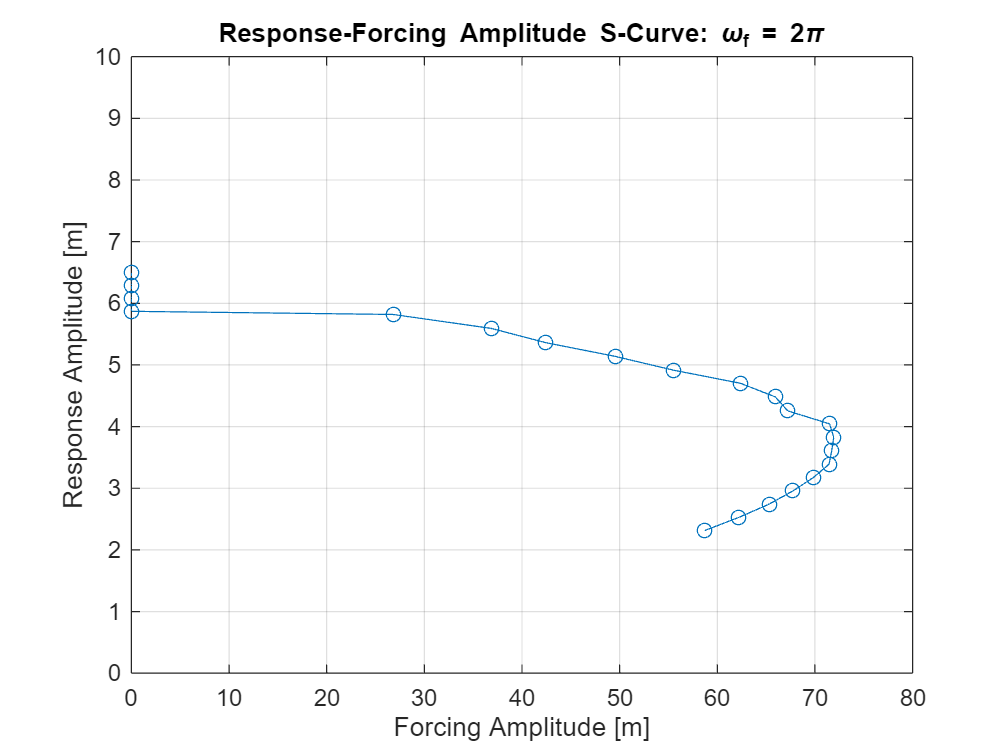

save("s_struct", "s_curve2")

% s_curve2(response_amplitudes'==0) = [] 
plot(s_curve2(:, 1), s_curve2(:, 2), '-o')
grid on;
title("Response-Forcing Amplitude S-Curve: \omega_f = 2\pi")
xlabel("Forcing Amplitude [m]")
ylabel("Response Amplitude [m]")
% xlim([0, 100])
ylim([0, 10])

a = linspace(2.3, 6.5, 21)
save("temp_s_curve", "")